# Network Model: Practice

## Minimal Spanning Tree

The minimal spanning tree links the nodes of a network using the smallest total length of connecting branches. A typical application occurs in the pavement of roads linking towns, either directly or passing through other towns. The minimal spanning tree solution provides the most economical design of the road system.

### Example 1: Cable connections

Midwest TV Cable Company is providing cable service to five new housing developments. **Figure 1** depicts possible TV connections to the five areas, with cable miles affixed on each arc. The goal is to determine the most economical cable network.

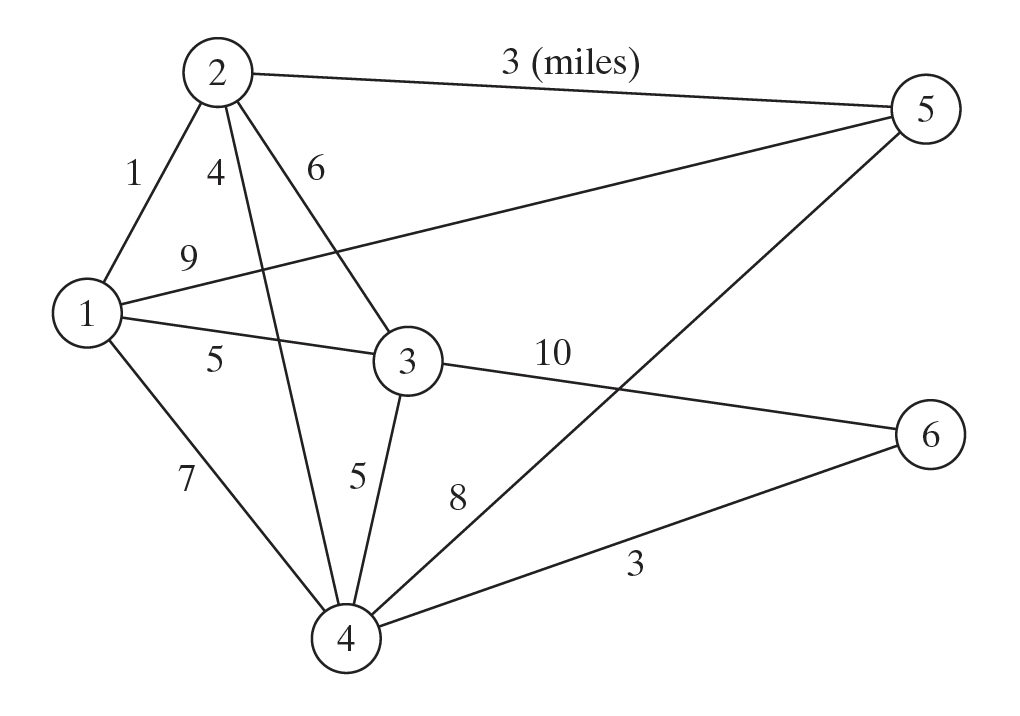

**Figure 1: **Cable connections for Midwest TV Company

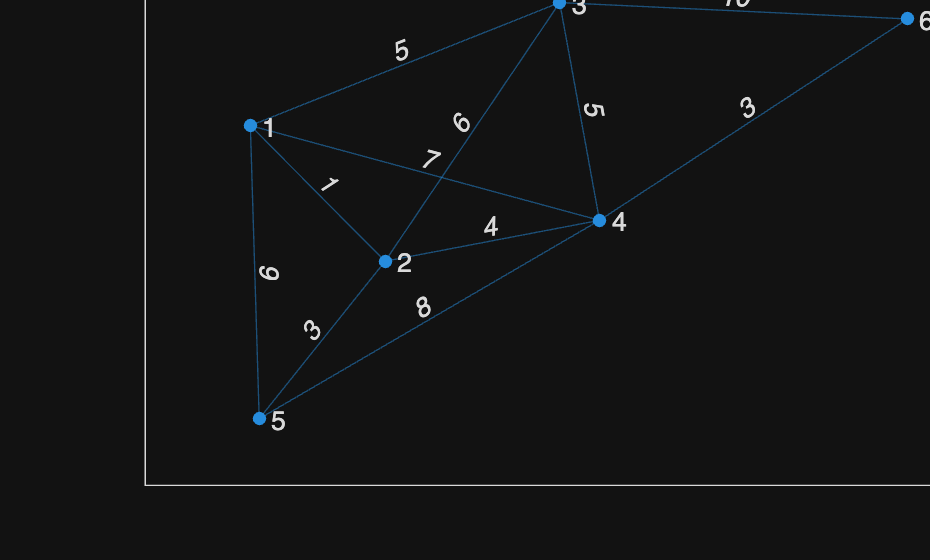

TR1 =   digraph with properties:

    Edges: [5×2 table]
    Nodes: [6×0 table]


D1 =      0     1     5     5     4     8


The distance of minimal spanning tree:


    16



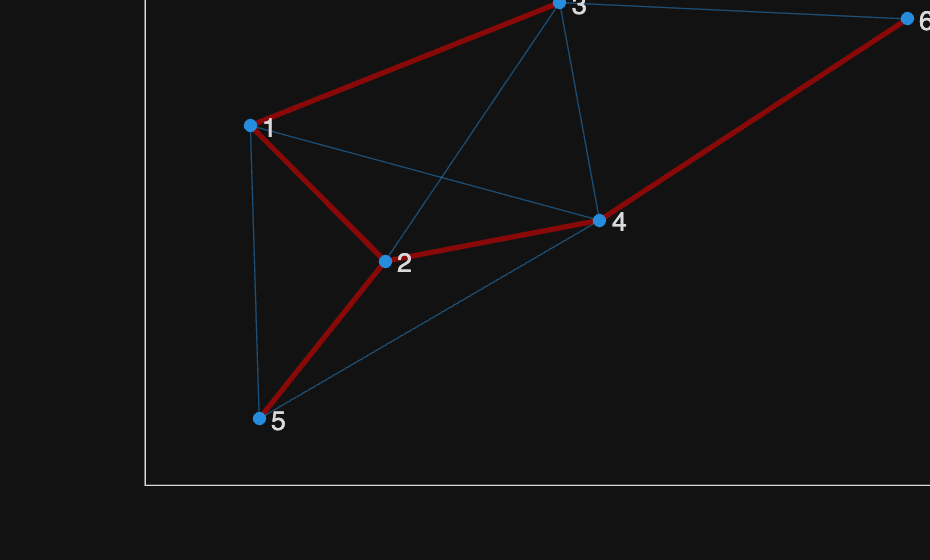

% Example 1



## Shortest-Route Problem

The shortest-route problem determines the shortest route between a source and destination in a transportation network. Other situations can be represented by the same model, as illustrated by the following examples.

### Example 2: Equipment Replacement

RentCar is developing a replacement policy for its car fleet over a 4-year planning horizon. At the start of each year, a car is either replaced or kept in operation for an extra year. A car must be in service from 1 to 3 years. **Table 1 **provides the replacement cost as a function of the year a car is acquired and the number of years in operation.

**Table 1: T**he replacement cost

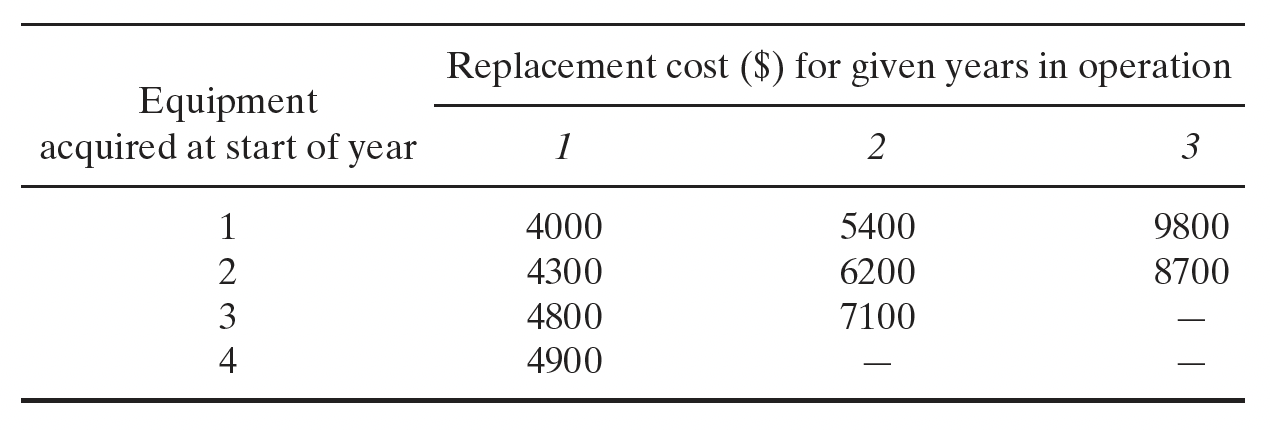

The problem can be formulated as a network in which nodes 1 to 5 represent the start of years 1 to 5. Arcs from node 1 (year 1) can reach nodes 2, 3, and 4 because a car must be in operation from 1 to 3 years. The arcs from the other nodes can be interpreted similarly. The length of each arc equals the replacement cost. The solution of the problem is equivalent to finding the shortest route between nodes 1 and 5.

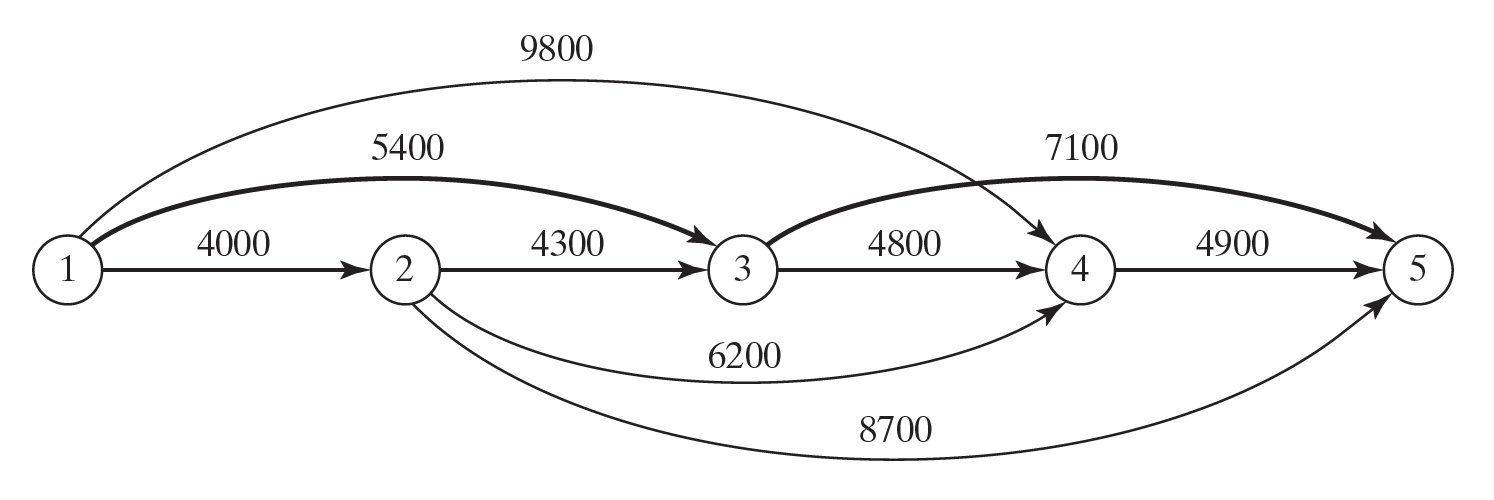

**Figure 2: **Equipment replacement problem as a shortest-route model

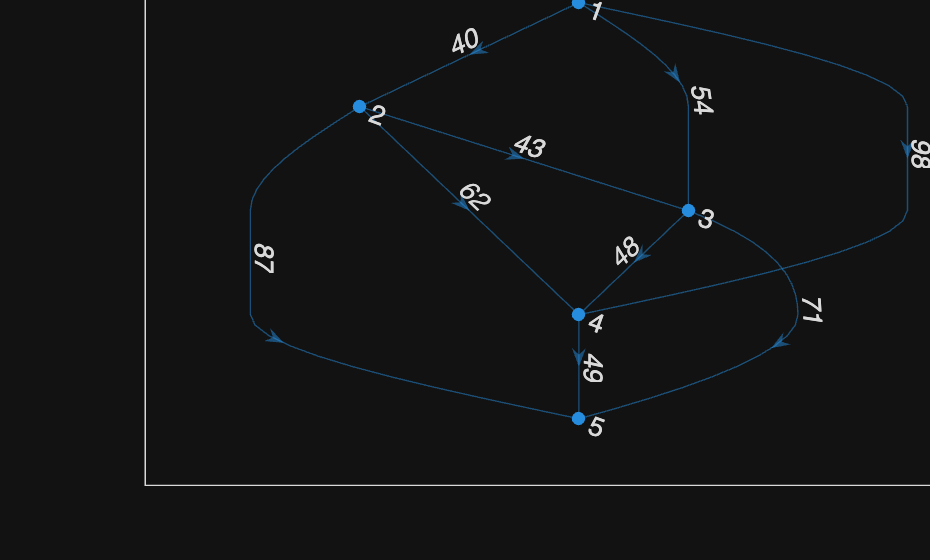

The shortest path from node 1 to node 5 is:


     1     3     5



The length of the shortest path is:


   125



% Example 2



### Example 3: Most Reliable Route

Smart drives daily to work. Having just completed a course in network analysis, Smart is able to determine the shortest route to work. Unfortunately, the selected route is heavily patrolled by police, and with all the fines paid for speeding, the shortest route may not be the best choice. Smart has thus decided to choose a route that maximizes the probability of not being stopped by police.

The network in **Figure 3 **shows the possible routes from home to work, and the associated probabilities of not being stopped on each segment. The probability of not being stopped on a route is the product of the probabilities of its segments. 

For example, the probability of not receiving a fine on the route $1\to 3\to 5\to 7$ is $0\ldotp 9\times 0\ldotp 3\times 0\ldotp 25=0\ldotp 0675$. Smart’s objective is to selectthe route that maximizes the probability of not being fined.

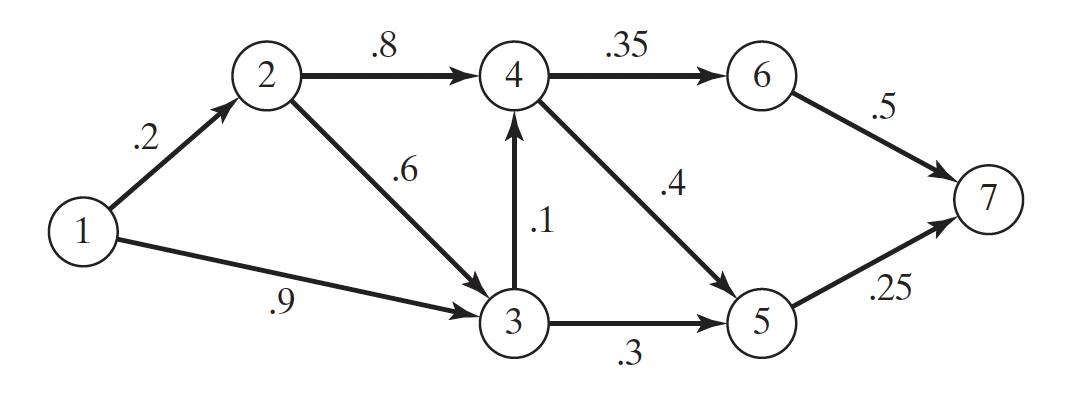

**Figure 3: **Most-reliable-route network model

The problem can be formulated as a shortest-route model by using logarithmic transformation to convert the product probability into the sum of the logarithms of probabilities—that is, $p_{1k} =p_1 \times p_2 \times \cdots \times p_k$ is transformed to ${\log \;p}_{1k} ={\log \;p}_1 +{\log \;p}_2 +\cdots +\log \;p_k$.

The two functions $p_{1k}$ and ${\log \;p}_{1k}$ are both monotone decreasing in $k$; thus **maximizing** $p_{1k}$ is equivalent to **maximizing** ${\log \;p}_{1k}$, which in turn is equivalent to **minimizing** $-{\log \;p}_{1k}$. Thus, replacing $p_j$ with ${-\log \;p}_j$ for all $j$ in the network, the problem is converted to the shortest-route network in **Figure 4**.

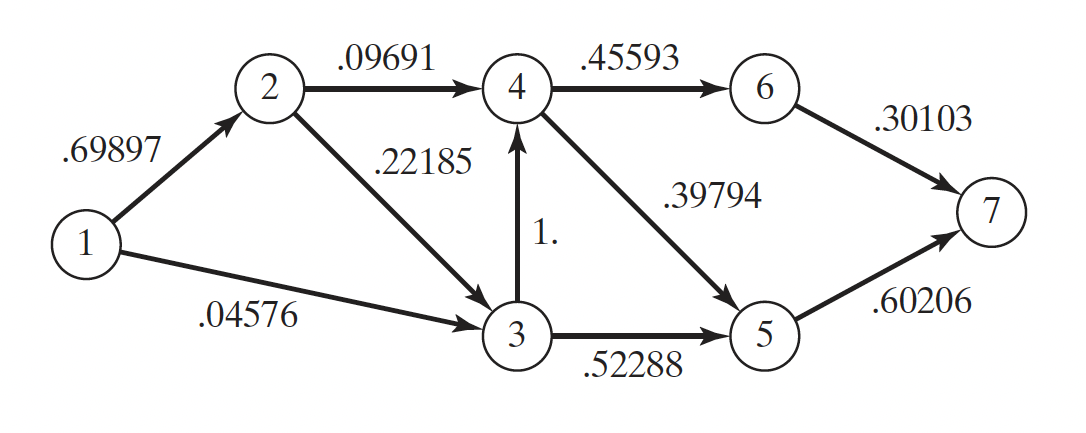

**Figure 4: **Most-reliable-route representation as a shortest-route model

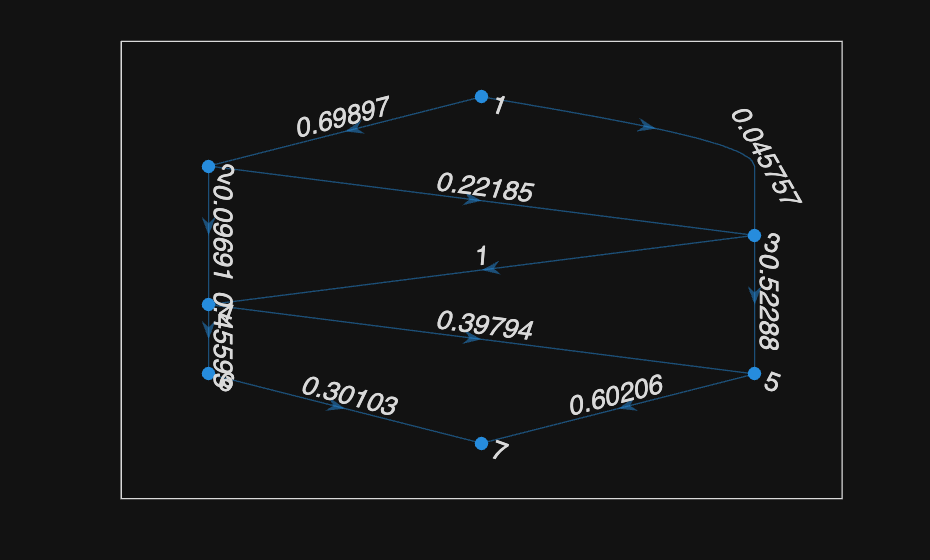

The shortest path from node 1 to node 7 is:


     1     3     5     7



The length of the shortest path is:


    1.1707



The maximum probability of not being stopped is:


    0.0675



% Example 3



## Maximal Flow Model

Consider a network of pipelines that transports crude oil from oil wells to refineries. Intermediate booster and pumping stations are installed at appropriate design distances to move the crude in the network. Each pipe segment has a finite discharge rate (or capacity) of crude flow. A pipe segment may be uni- or bidirectional, depending on its design. **Figure 5** demonstrates a typical pipeline network. The goal is to determine the maximum flow capacity of the network. The solution of the proposed problem requires adding a single source and a single sink using unidirectional infinite capacity arcs, as shown by dashed arcs in **Figure 5**.

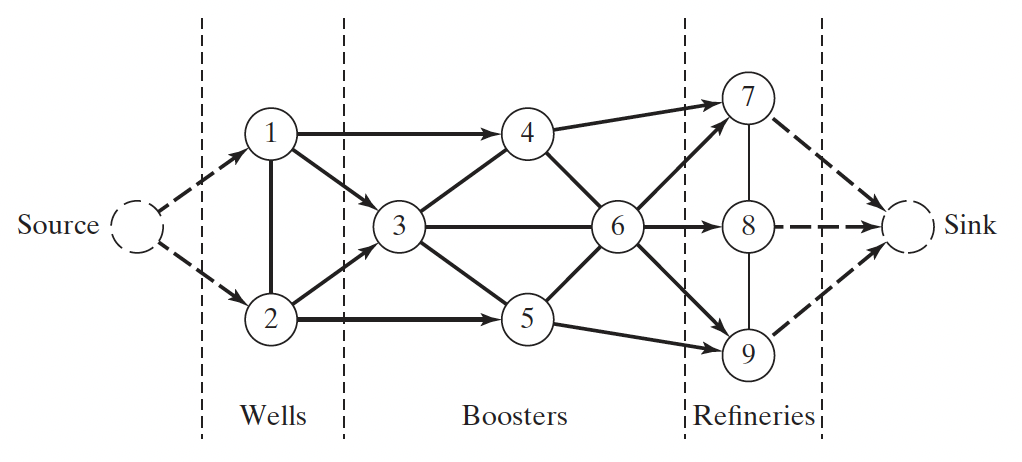

**Figure 5:** Capacitated network connecting wells and refineries through booster stations

### Example 4: Maximal Flow

Determine the maximal flow in the following network (**Figure 6**).

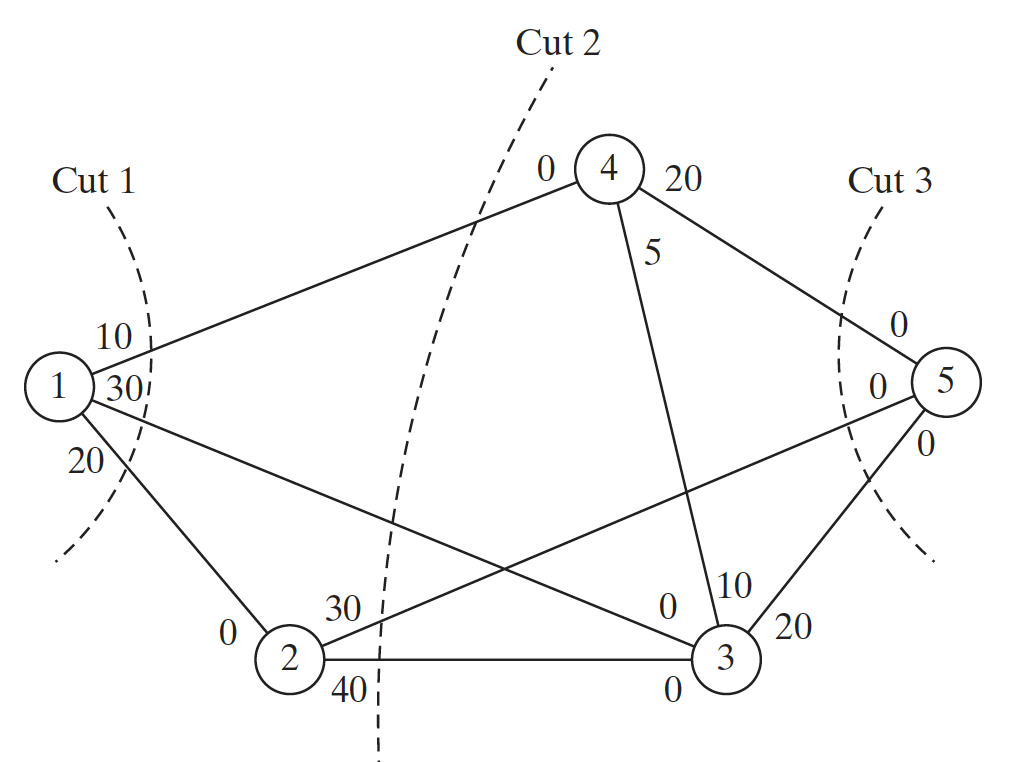

**Figure 6:** Networks for Example 4

Also answer the following questions:

- Determine the surplus capacities for all the arcs.

- Determine the amount of flow through nodes 2, 3, and 4.

- Can the network flow be increased by increasing the capacities in the directions $3\to 5$ and $4\to 5$?

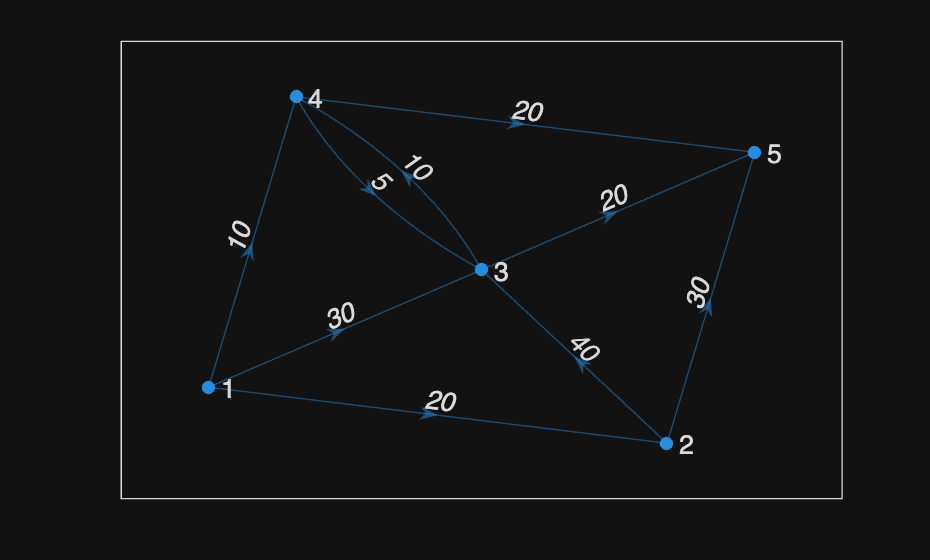

The maximum flow from node 1 to node 5:


    60



ans =      1     2    20
     1     3    30
     1     4    10
     2     5    20
     3     4    10
     3     5    20
     4     5    20


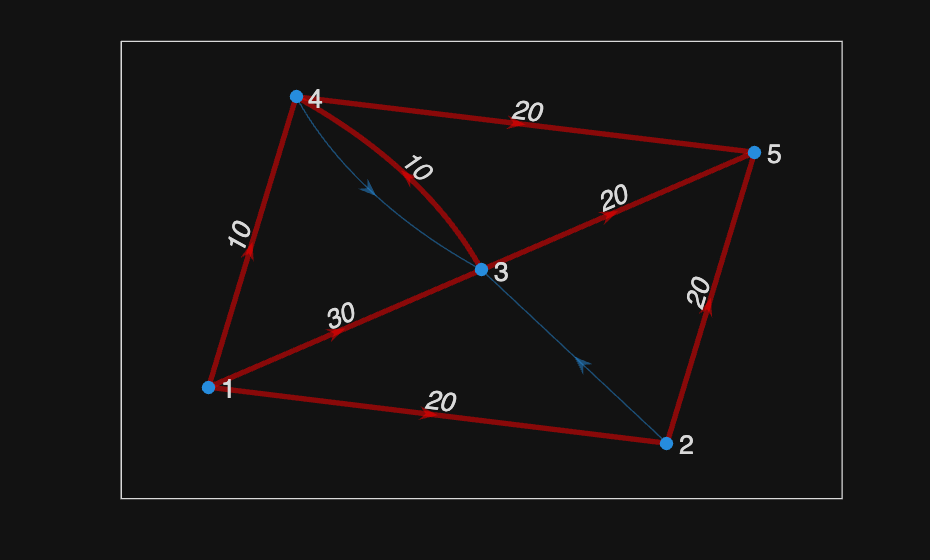

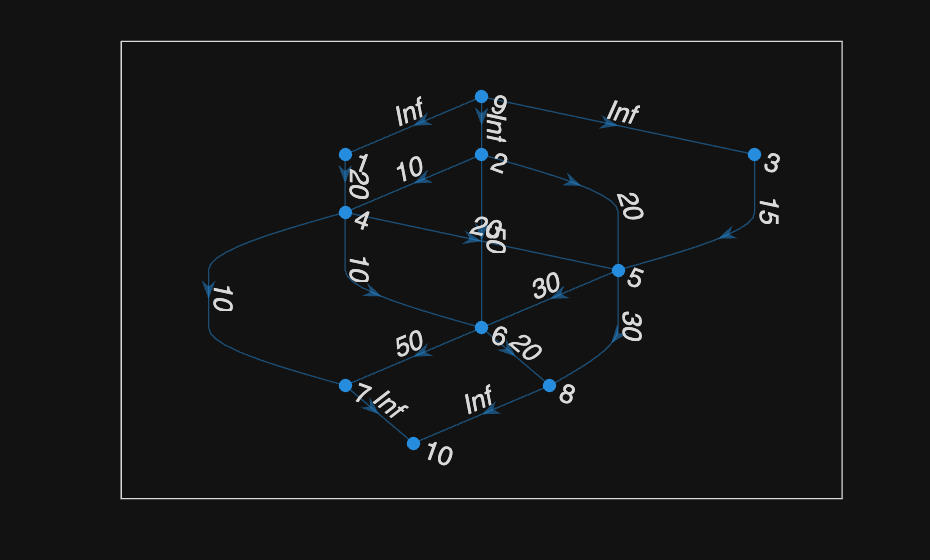

The maximum flow from node 9 (source) to node 10 (sink):


   110



ans =      1     4    20
     2     4     5
     2     5    20
     2     6    50
     3     5    15
     4     5     5
     4     6    10
     4     7    10
     5     6    10
     5     8    30
     6     7    50
     6     8    20
     7    10    60
     8    10    50
     9     1    20


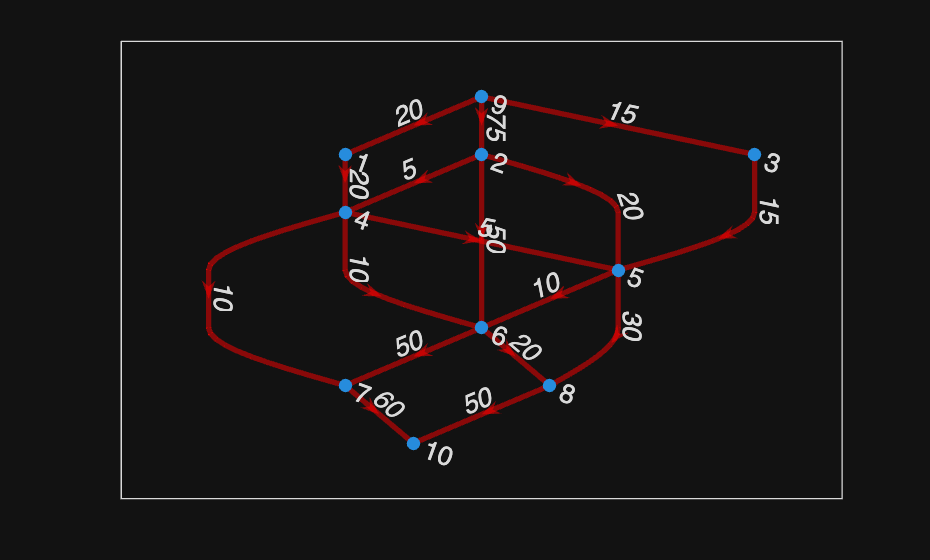

% Example 4

1. Surplus Capacities

Link 2-3: 

Link 2-5: 

Link 4-3: 

2. 

Flow through nodes 2: 

Flow through nodes 3: 

Flow through nodes 4: 

3. 

### Example 5: Pipeline Network

Three refineries send a gasoline product to two distribution terminals through a pipeline network. Any demand that cannot be satisfied through the network is acquired from other sources. The pipeline network is served by three pumping stations, as shown in **Figure 6**. The product flows in the network in the direction shown by the arrows. The capacity of each pipe segment (shown directly on the arcs) is in million bbl per day.

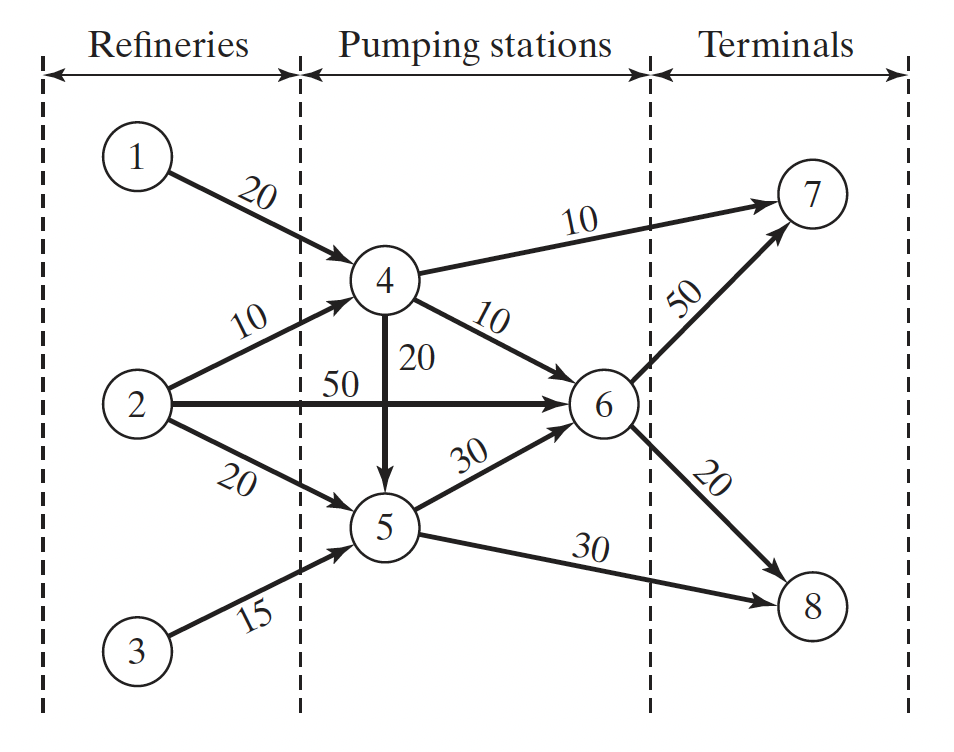

**Figure 6:** Pipeline Network

Determine the following:

- The daily production at each refinery that matches the maximum capacity of the network.

- The daily demand at each terminal that matches the maximum capacity of the network.

- The daily capacity of each pump that matches the maximum capacity of the network.

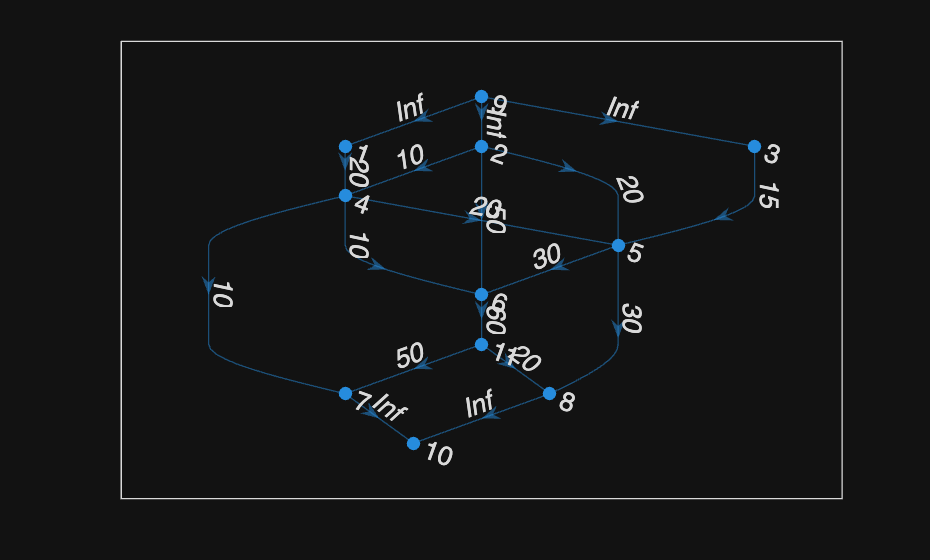

The maximum flow from node 9 (source) to node 10 (sink):


   100



ans =      1     4    20
     2     5    20
     2     6    50
     3     5    10
     4     6    10
     4     7    10
     5     8    30
     6    11    60
     7    10    60
     8    10    40
     9     1    20
     9     2    70
     9     3    10
    11     7    50
    11     8    10


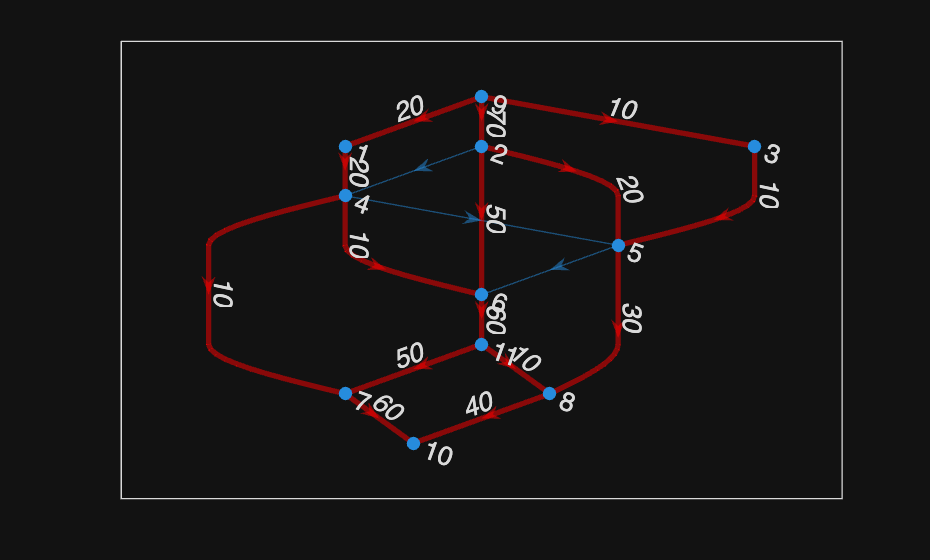

% Example 5



1. The daily production at each refinery

Refinery 1: 

Refinery 2:

Refinery 3: 

2. The daily demand at each terminal 

Terminal 7: 

Terminal 8: 

3. The daily capacity of each pump 

Pump 4: 

Pump 5: 

Pump 6: 

### Example 6: Pipeline Network (cont.)

Suppose that the maximum daily capacity of pump 6 in the network of **Figure 6** is limited to 60 million bbl per day. Remodel the network to include this restriction. Then determine the maximum capacity of the network.

% Example 6



`End-of-file`

`Pongsun B.`

`2025-10-16`